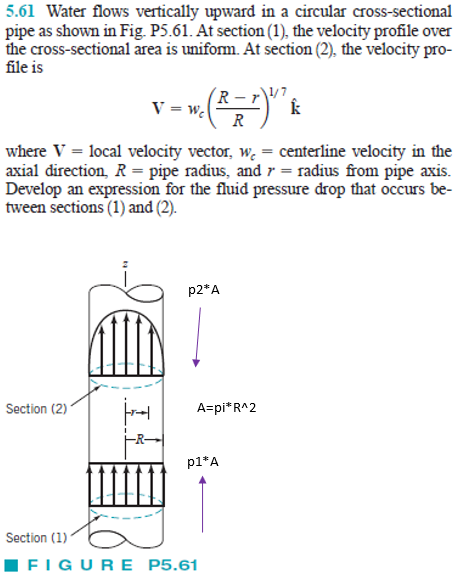

# RETIRED!!!!!!!!!

# constants

syms rho h g R;
u = symunit;
A = sympi*R^2;
Ww = rho*A*h*g

$$Ww = \pi \,R^{2}\,g\,h\,\rho$$

# inflow properties

syms p1 V1;
mdot1(V1) = rho*A*V1;

# outflow properties

syms wc r;
V2(r) = wc*((R-r)/R)^(1/7);
mdot2 = int(rho*V2*2*sympi*r, r, [0 R]);

# conservation of mass

V1 = solve(mdot1 == mdot2, V1)

$$V1 = \frac{49\,\mathrm{wc}}{60}$$

# conservation of momentum (z-direction)

syms p2_p1;
p2_p1 = solve(-p2_p1*A-Ww == -mdot1(V1)*(V1)+int(V2*rho*V2*2*sympi*r, r, [0 R]), p2_p1)

$$p2\_p1 = -\frac{49\,\rho \,{\mathrm{wc}}^{2}}{3600}-g\,h\,\rho$$